### Linear Algebra and Programming Skills

*Dr Jon Shiach, Department of Computing and Mathematics, Manchester Metropolitan University*

# Plotting the Mandelbrot Set

The [Mandelbrot set](https://en.wikipedia.org/wiki/Mandelbrot_set) is defined by points in the complex plane $z_0\in \mathbb{C}$ where the iterative scheme

$z_{n+1} = z_n^2 + z_0$,

remains bounded. If, after a specified number of iterations, $|z_n|\leq 2$ then $z_0$ is a member of the Mandelbrot set. The write a program to determine which values of $z_0$ are members of the Mandelbrot set we can substitute $z=x+yi$ where $i^2=-1$ into the iterative scheme and derive expressions for updating the real and imaginary parts separately


$$\qquad \quad \, z_{n+1} = z_n^2 + z_0 \\
x_{n+1} + y_{n+1}i = (x_n + y_ni)^2 + x_0 + y_0i \\
\qquad \qquad \quad \! = x_n^2 + 2x_n y_n i - y_n^2 + x_0 + y_0i \\
\qquad \qquad \quad \!= (x_n^2 - y_n^2 + x_0) + (2x_n y_n + y_0)i.$$
 

Therefore $x_{n+1}=x_n^2-y_n^2+x_0$ and $y_{n+1}=2x_ny_n+y_0$.

The program below generates the Mandelbrot set over the domain $x\in[-2,1]$, $y\in[-1.2,1.2]$. The iterative scheme for each point $z_0$ are calculated until $|z_n|>2$ or $n=100$ whichever comes earlier and the value of $n$ is recorded in an image array so that when plotted the colours provide an indication of the distance of each point from the Mandelbrot set. A [normalised iteration count](http://www.iquilezles.org/www/articles/mset_smooth/mset_smooth.htm) has been applied to smooth out the colours in the plot.

The function mandelbrot_set is defined at the end of this live script.

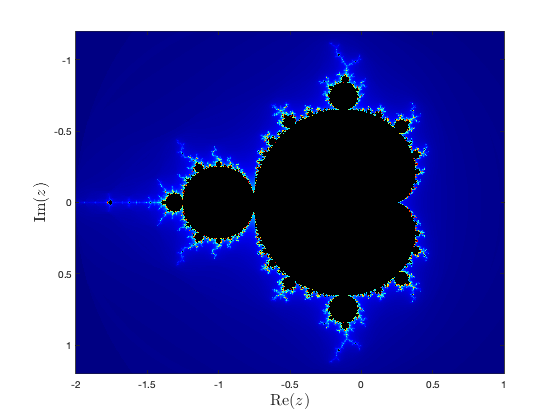

% Define parameters
height = 900;  % number of pixels
width = 1200;   
maxiter = 100; % maximum number of iterations
xmin = -2;     % real axis limits
xmax = 1;
ymin = -1.2;   % imaginary axis limits
ymax = 1.2;

% Generate co-ordinate arrays
x = linspace(xmin, xmax, width);
y = linspace(ymin, ymax, height);

% Generate Mandelbrot set
img = mandelbrot_set(x, y, maxiter);

% Add layer of black to the 'jet' colormap for those points that are
% members of the Mandelbrot set
cmap = [ jet ; zeros(1, 3) ];
colormap(cmap)

% Plot Mandelbrot set
imagesc(x, y, img(end:-1:1,:))
axis equal tight
xlabel('Re$(z)$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('Im$(z)$', 'Interpreter', 'latex', 'FontSize', 16)

We can explore the Mandelbrot set by changing the values of `xmin`, `xmax`, `ymin`, `ymax` and `maxiter` and calling the `mandelbrot_set` function again to regenerate the `img` array. Uncomment/comment the lines below to see the results.

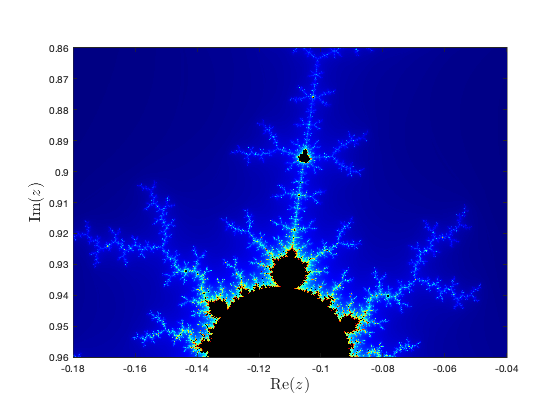

% Define real and imaginary values
xmin = -0.18; xmax = -0.04; ymin = 0.86; ymax = 0.96;
% xmin = -0.8; xmax = -0.77; ymin = 0.135; ymax = 0.155;
% xmin = -0.134; xmax = -0.124; ymin = 0.984; ymax = 0.992;
% xmin = -0.749; xmax = -0.747; ymin = 0.1225; ymax = 0.124;
maxiter = 200;

% Generate Mandelbrot set
x = linspace(xmin, xmax, width);
y = linspace(ymin, ymax, height);
img = mandelbrot_set(x, y, maxiter);

% Plot Mandelbrot set
imagesc(x, y, img(end:-1:1,:))
axis equal tight
xlabel('Re$(z)$', 'Interpreter', 'latex', 'FontSize', 16)
ylabel('Im$(z)$', 'Interpreter', 'latex', 'FontSize', 16)

## Functions

The function below generates the Mandelbrot set for real and imaginary values $x$ and $y$ and ceasing iterations when `maxiter` is reached. This function makes use of **array masking** where the array `i`  is the same size as the `img` array that contain boolean values `true` or `false` which are then used to index the arrays `X`, `Y`, and `img`.

function img = mandelbrot_set(x, y, maxiter)

% This function generates an image array containing the Mandelbrot set for
% the real and imaginary values stored in x and y.

% Initialise pixel arrays
height = length(y);         % size of image array
width = length(x);
img = zeros(height, width); % image array
[X0, Y0] = meshgrid(x, y);  % starting values of x and y
X = zeros(size(X0));        % current values of x
Y = zeros(size(X0));        % current values of y
Xold = zeros(size(X0));     % values of x from previous iteration 

% Iteration loop
for n = 1 : maxiter
    
    % Determine pixels that are still inside of the Mandelbrot set 
    % (|x + iy| < 2)
    i = X .^ 2 + Y .^ 2 < 4;
    
    % Calculate new values of X and Y
    X(i) = X(i) .^ 2 - Y(i) .^ 2 + X0(i);
    Y(i) = 2 * Xold(i) .* Y(i) + Y0(i);
    Xold = X;

    % Increment those points inside the Mandelbrot set by 1.
    img(i) = img(i) + 1;
    
    % Apply normalised iteration count to those points who have left the
    % Mandelbrot set in the current iteration
    i = img == n - 1;
    img(i) = n + 1 - log(log(X(i) .^ 2 + Y(i) .^ 2) / log(2)) / log(2);
    
end

end